# Drinking container classifier

*If you want to try out the classifier immediately, please run this section.*

load('matlab.mat');

## Identifying Classes of drinking container

### Differences between classes

In this classifier, it has four classes which is Bottle, Can, Cup and Drink Box. Each of the container has different features that can differentiate itself from others.

- Bottle       : narrow neck or mouth and usually no handle

- Can          : metal container that has pop-tab

- Cup          : small bowl-shaped container, typically having a handle.

- Drink Box : cuboid container

    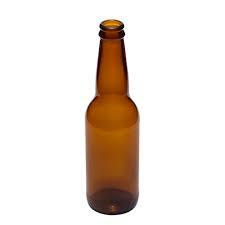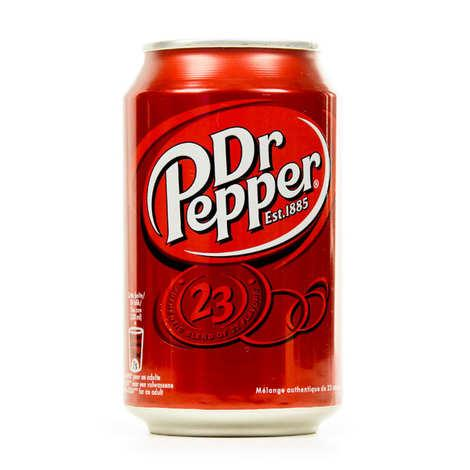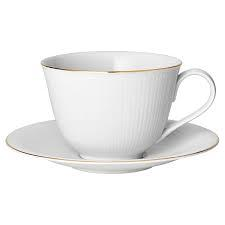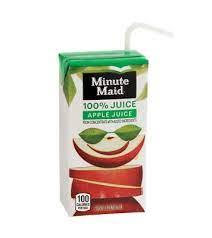

## Data Preparation

### Obtaining the datasets

The images datasets were obtained by downloading images from [Google.com](http://google.com) sorted according to respective classes.

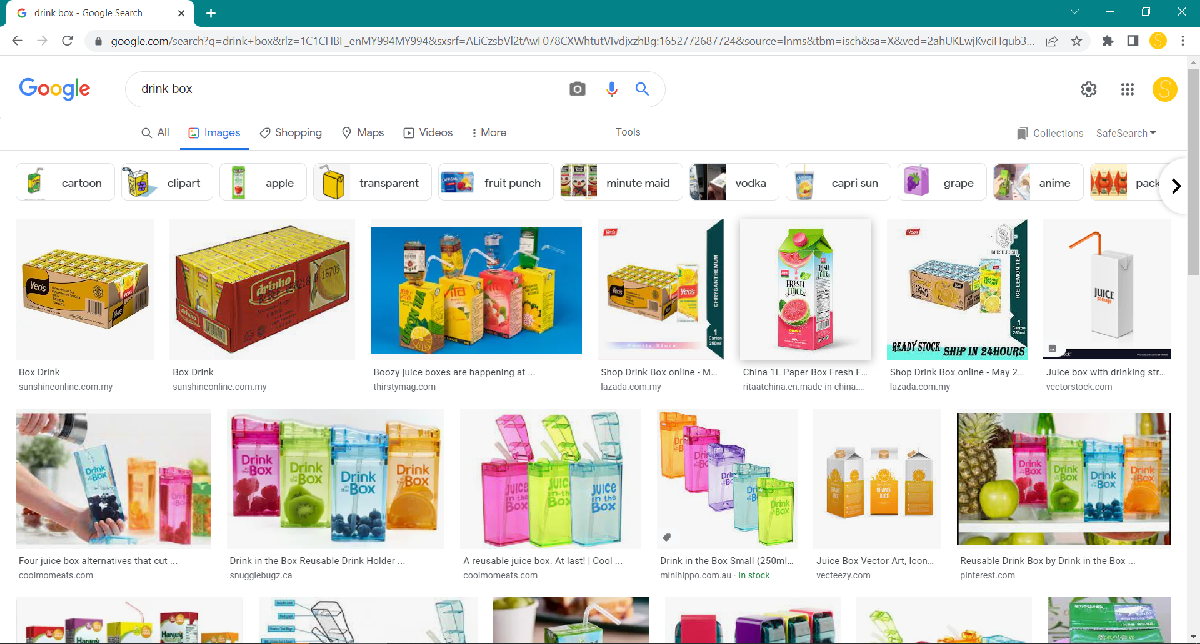

By using Chrome extension called Image Downloader, multiple images can be downloaded at once. Here is the total images for each class.

Path = fullfile("drink/");
data = imageDatastore(Path,IncludeSubfolders=true,LabelSource="foldernames");

data.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        76  
    can           67  
    cup           76  
    drink box     62  


### Data augmentation

Since the dataset collected is in small size, data augmentation can be done to increase the number of images.

Rotating, scaling and reflecting the images will increases the dataset three times.

Path = fullfile("containerx3/");
imds = imageDatastore(Path,IncludeSubfolders=true,LabelSource="foldernames");

imds.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        300 
    can           256 
    cup           300 
    drink box     240 


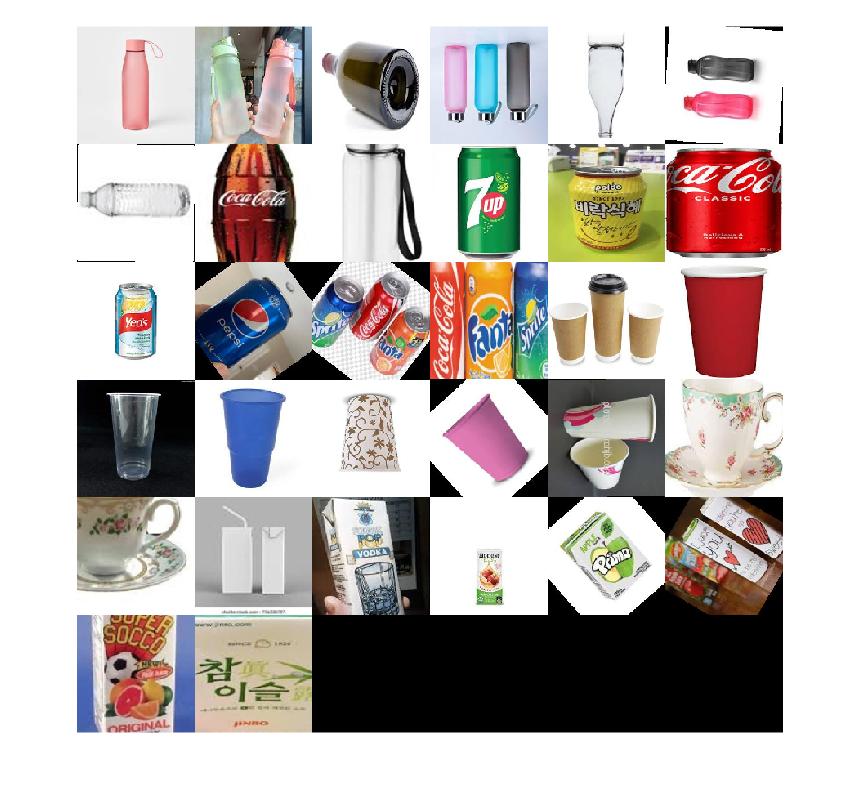

figure
montage(imds.Files(1:35:end))

### Splitting the data

The dataset is splitted into two for training (60%) and testing (40%).

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.6);

imdsTrain.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        180 
    can           154 
    cup           180 
    drink box     144 


imdsValidation.countEachLabel

ans = 4×2 table
      Label      Count
    _________    _____

    bottle        120 
    can           102 
    cup           120 
    drink box      96 


## Image Classification

### Load the network and modify the layers

By using a pretrained network GoogLeNet, we can modify the final layers so it can work with the data. Modifying the layers is called 'Transfer Learning'.

net = googlenet;

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

lgraph = layerGraph(net);

numClasses = numel(categories(imdsTrain.Labels));

newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);

lgraph = replaceLayer(lgraph,'loss3-classifier',newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

After modifying the layer, we set the training options with max epoch of 6 and learning rate is 0.0003.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Plots','training-progress');

### Network Training

Let's train the network.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       50.00% |       1.8095 |          0.0003 |
|       1 |          50 |       00:01:19 |       70.00% |       1.5055 |          0.0003 |
|       2 |         100 |       00:02:40 |      100.00% |       0.0290 |          0.0003 |
|       3 |         150 |       00:04:30 |       90.00% |       0.1212 |          0.0003 |
|       4 |         200 |       00:06:18 |      100.00% |       0.0769 |          0.0003 |
|       4 |         250 |       00:08:30 |      100.00% |       0.0156 |          0.0003 |
|       5 |         300 |  

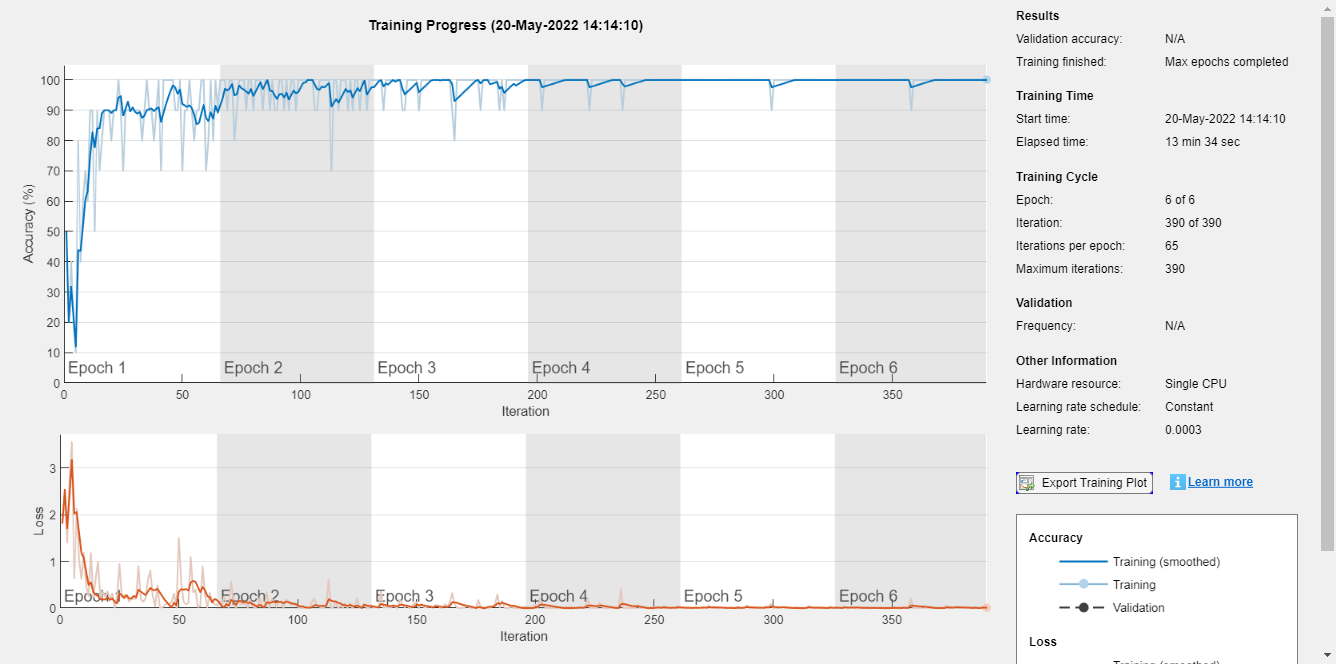

newNet = trainNetwork(augimdsTrain,lgraph,options);

## Testing the Network

After data training, we test the network with the testing data to see how accurate the classifier

[YPred,probs] = classify(newNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels);
accuracy

accuracy = 0.9939

Print out the confusion matrix to see how accurate the classifier for each class.

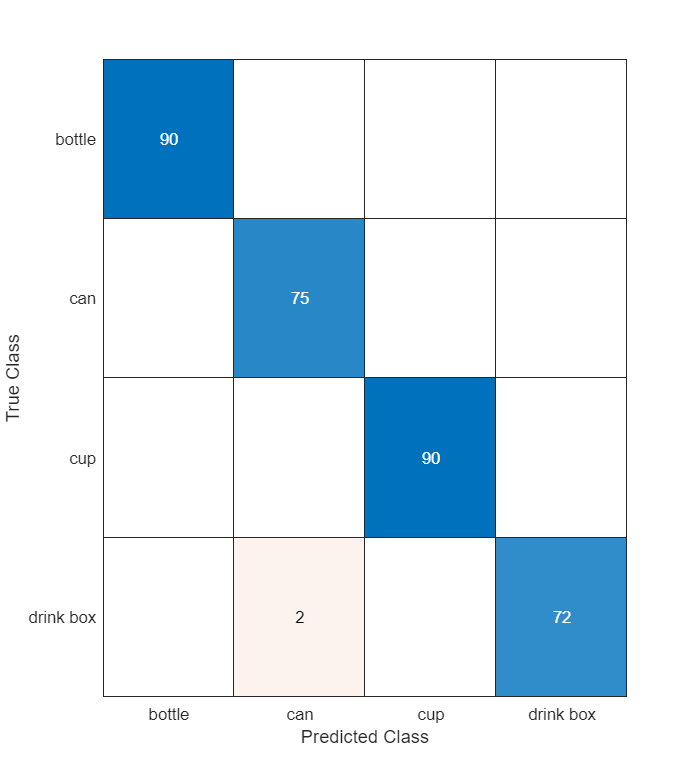

result =   ConfusionMatrixChart with properties:

    NormalizedValues: [4×4 double]
         ClassLabels: [4×1 categorical]

  Show all properties


confMat = confusionmat(YPred,imdsValidation.Labels);
label = unique(imdsValidation.Labels);
result = confusionchart(confMat,label)

## Try it out with your own image!

Insert your image in **guess** and run the section.

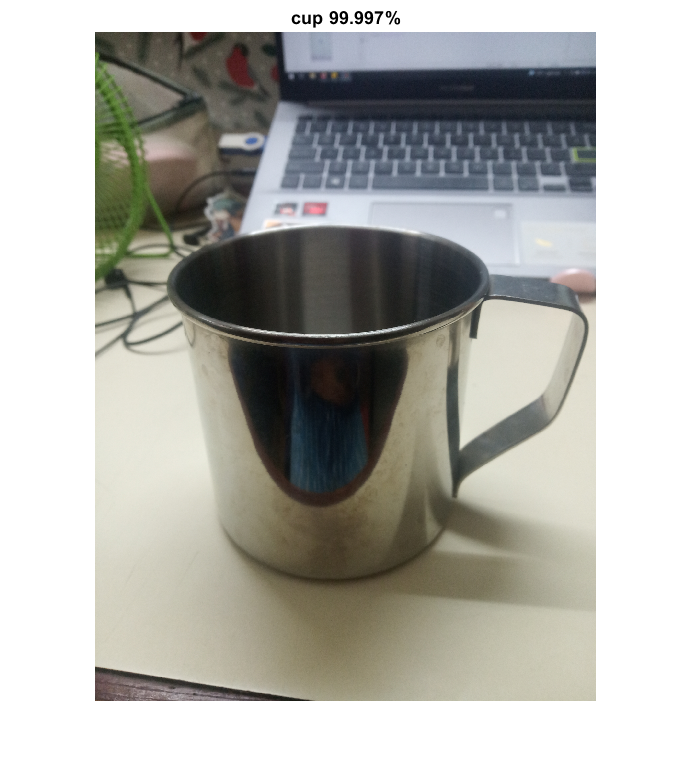

guess=imread("cup2.jpg");
adjust=augmentedImageDatastore(inputSize(1:2),guess);

[i,score]=classify(newNet,adjust);

str = string(i)+" "+score(i)*100+"%";
imshow(guess)
title(str)